# IIR Filter Designer

Infinite Impulse Response (IIR) filters are an alternative to Finite Impulse Response (FIR) filters.  Because they are implemented recursively, they can use fewer microprocessor cycles and lower amounts of memory to implement.

However, because they involve using feedback they can become unstable under some circumstances where rounding becomes significant.  Typically IIR filters are implemented using floating point data types.

This tool will allow you to design multiple types of filters with varying filter order and cutoff frequencies.  Lowpass, highpass, bandpass and bandstop filters are all supported.  Additionally, both Butterworth and Chebyshev filters are able to be designed.

The figure below shows a comparison of a 4th order Butterworth and Chebyshev lowpass filters.   Butterworth filters are characterized by their flat passband and decreasing stopband performance.  Chebyshev filters can roll off faster than than Butterworth filters, but trade this for passband and stop band ripple


clearvars; close all; clc

%  Print MATLAB flag
printMATLABFlag = true;


Set the sampling frequency of the system.  For the breathing rate system we often a sampling frequency expressed in Breaths Per Minute.  This can be converted to a sampling frequency in time using


$$f_{hz} = f_{BPM}\times \frac{1}{60}\frac{min}{sec}$$


Likewise the sampling frequency in hertz can be converted to breaths per minute using:


$$f_{BPM}= f_{hz} \times 60 \frac{sec}{min}$$


Typically the breathing rate system is using a sampling rate of $10 Hz$ or $600 BPM$.


samplingFreq = 600;   % Sampling frequency in Hz

%  When MATLAB computes frequency response using 'freqz' it computes it from 0 to the
%  Nyquist frequency which is 1/2 of the sampling frequency.  This
%  frequency is normalized to the radian frequency.  The sampling rate
%  corresponds to 2*pi and the nyquist rate to pi.

nyquistFreq = samplingFreq/2; % BPM folding frequency

%  Create a vector of frequencies from 0 to pi and convert them to the sample rate

w = linspace(0,pi,4096); % freqz() requires 0..pi range
fbpm = (nyquistFreq/pi)*w;


Choose the filter type (Butterworth or Chebyshev) and the filter topology (LPF, HPF, BPF, BSF).  Here are some examples of various filter types and topologies.

% ************************************************************
% Create Butterworth or Chebyshev filters.

filterType = "chebyshev";  %  Filter type Butterworth or Chebyshev
filterTopology = "bandpass";  %  Filter topology LPF, HPF, etc..


An additional parametr for the Chebyshev filter is the amount of ripple in the passband.  If Chebyshev is the filter type selected then set the amount of ripple in decibels (dB).

rippleDb = 1;  %  Passband ripple for a Chebyshev filter

The order of the filter will determine the number of poles in the filter.  The greater the number of poles the steeper is the filter response.  However more poles increases the filter complexity.  The figure below shows the difference between a filter with 3 poles and 5 poles.


filterOrder = 5;  % Order of the filter.  Determines the number of poles in the filter

Choose the corner frequency (sometimes called the cutoff frequency).  This determines the location of the passband of the filter.  In the case of the lowpass filter you only need to specify one value.  With a bandpass and stop band you will need to specify the lower corner frequency and the upper corner frequency.  The figures below describe these values.  The units for the corner frequency will be the same as the sampling frequency.

### If the filter is a LPF or HPF, enter the corner frequency below

lpf_hpf_cornerFreq = 12;  %  Filter corner frequency



### If the filter is a BPF or BSF, enter both the upper and the lower corner frequecies below

lower_bpf_bsf_cornerFreq = 12;  %  Lower corner frequency for BPF and BSF
upper_bpf_bsf_cornerFreq = 40;  %  Upper corner frequency for BPF and BSF


xDisplayRange = [0 100];

%  Comment select the filter type that you want paramters for.  That is
%  Butterworth or Chebyshev
%
%  Select the filter (low pass or highpass) by changing the value
%  of the variable fType to either 'LOW' or 'HIGH'

%  Find the coefficients of the filter in the direct form for either the
%  Butterworth of the Chebyshev filters.  The input parameters are the
%  cornerfrequency (normalized to the Nyquist frequency) and the filter
%  type (LPF, HPF, BPF or BSF)

% switch lower(filterTopology)
%
%     case {'lowpass','highpass'}
%         cornerFreq = lpf_hpf_cornerFreq;
%
%     case {'bandpass','bandstop'}
%         cornerFreq = [lower_bpf_bsf_cornerFreq, upper_bpf_bsf_cornerFreq];
%
%     otherwise  %  Assume lowpass, but should never get here
% end


switch lower(filterType)

    case {'butterworth'}

        %
        %-------- Butterworth Filter -------------------------------
        %


        switch lower(filterTopology)

            case {'low','high'}
                cornerFreq = lpf_hpf_cornerFreq;
                comment_txt = sprintf('BWRTH %s, order %d, %d BPM\n', filterTopology, filterOrder, cornerFreq);


            case {'bandpass','stop'}
                cornerFreq = [lower_bpf_bsf_cornerFreq, upper_bpf_bsf_cornerFreq];
                comment_txt = sprintf('BWRTH %s, order %d, [%d %d] BPM\n', filterTopology, filterOrder, cornerFreq);

            otherwise %  Assume LPF/HPF
                cornerFreq = lpf_hpf_cornerFreq;
                comment_txt = sprintf('BWRTH %s, order %d, %d BPM\n', filterTopology, filterOrder, cornerFreq);
        end

        [b,a] = butter(filterOrder, cornerFreq/nyquistFreq, filterTopology);

    case {'chebyshev'}

        %
        % -------- Chebyshev Filter ----------------------------------
        %

        switch lower(filterTopology)

            case {'low','high'}
                cornerFreq = lpf_hpf_cornerFreq;
                comment_txt = sprintf('CHEBY %s, order %d, R = %0.1f, %d BPM\n', filterTopology, filterOrder, rippleDb, cornerFreq);


            case {'bandpass','stop'}
                cornerFreq = [lower_bpf_bsf_cornerFreq, upper_bpf_bsf_cornerFreq];
                comment_txt = sprintf('CHEBY %s, order %d, R= %0.1f, [%d %d] BPM\n', filterTopology, filterOrder, rippleDb, cornerFreq);

            otherwise  %  Assume lowpass/highpass
                cornerFreq = lpf_hpf_cornerFreq;
                comment_txt = sprintf('CHEBY %s, order %d, R = %0.1f, %d BPM\n', filterTopology, filterOrder, rippleDb, cornerFreq);
        end

        [b,a] = cheby1(filterOrder, rippleDb, cornerFreq/nyquistFreq, filterTopology);
end



### Here is the z-transform of the filter:


% ************************************************************
% Console output transfer function
Tsmpl = 0.1;
Tfilt = tf(b,a,Tsmpl,'variable','z^-1')

Tfilt =
 
                                                                             
  7.317e-06 - 3.659e-05 z^-2 + 7.317e-05 z^-4 - 7.317e-05 z^-6 + 3.659e-05 z^
                                                                             
                                                         -8 - 7.317e-06 z^-10
                                                                             
  ---------------------------------------------------------------------------
                                                                             
  1 - 9.368 z^-1 + 39.83 z^-2 - 101.2 z^-3 + 170.1 z^-4 - 197.8 z^-5         
                                                                             
             + 161 z^-6 - 90.64 z^-7 + 33.77 z^-8 - 7.519 z^-9 + 0.7599 z^-10
                                                                             
 
Sample time: 0.1 seconds
Discrete-time transfer function.



### The complex Zeros of the transfer function (roots of the numerator) are shown below:

%---------------------------------------------------
% Console output pole and zero locations
zeros_b = roots(b)

zeros_b =   -1.0004 + 0.0000i
  -1.0001 + 0.0004i
  -1.0001 - 0.0004i
  -0.9997 + 0.0002i
  -0.9997 - 0.0002i
   1.0005 + 0.0000i
   1.0002 + 0.0005i
   1.0002 - 0.0005i
   0.9996 + 0.0003i
   0.9996 - 0.0003i


### The complex Poles of the transfer function (roots of the denominator) are shown below:

poles_a = roots(a)

poles_a =    0.8966 + 0.3967i
   0.8966 - 0.3967i
   0.9012 + 0.3139i
   0.9012 - 0.3139i
   0.9337 + 0.2150i
   0.9337 - 0.2150i
   0.9860 + 0.1250i
   0.9860 - 0.1250i
   0.9666 + 0.1508i
   0.9666 - 0.1508i


### The complex Poles of the transfer function can also be expressed in terms of frequency by computing the magnitude of the complex poles:

pole_wn = abs(poles_a) % display pole magnitudes

pole_wn =     0.9805
    0.9805
    0.9543
    0.9543
    0.9581
    0.9581
    0.9939
    0.9939
    0.9783
    0.9783


### Plot the locations of the zeros and the poles and a Polar Plot in the Z-Domain.  X's indicate Pole Positions and O's indicate the Zero positions.  The circle is where the magnitude of Z = 1

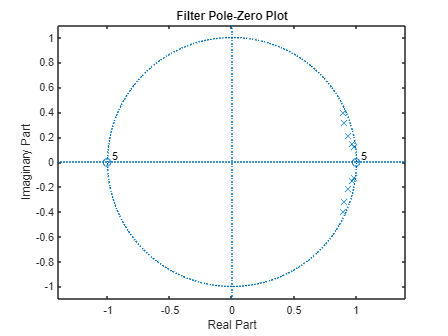

%---------------------------------------------------
% Console output pole-zero plot for nPole pole filter
fig1 = figure(1);
zplane(b,a);
title('Filter Pole-Zero Plot');

figLoc = [150 150 300 250];
% set(fig1,'position',figLoc);



### Plot the Impulse Response of the filter

%---------------------------------------------------
% Plot impulse response

[hir,smpl] = impz(b,a);
hsr = cumsum(hir);
maxN = find((abs(hir)/max(hir)) > 0.01, 1,'last');

fig2 = figure(2);
plot(smpl,hir,'b','linewidth',2); grid on;
% stem(smpl,hir,'b','linewidth',2); grid on;
% xlim([0 maxN]);
xlabel('sample');
title('Impulse Response');
% set(fig2,'position',figLoc);


### The filter is made up of a number of individual filters cascaded together.  Plot the individual frequency response of each filter and then the combined frequency response.

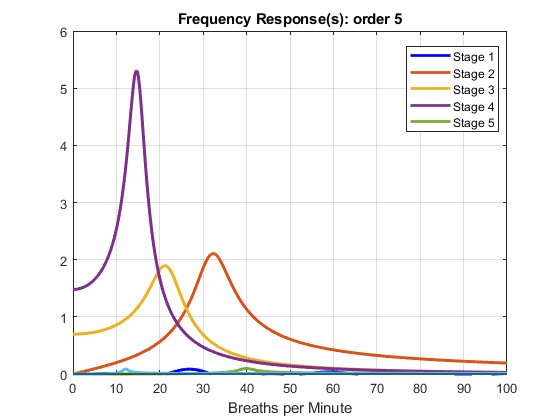

%---------------------------------------------------
% Plot cascade and sos component frequency response

[sos,G1] = tf2sos(b,a); % display second order systems
[rsos,~] = size(sos);
Gpole = G1^(1/filterOrder);
Gstage = ones(1,rsos)*(Gpole^2);
if (mod(filterOrder,2) == 1); Gstage(1) = Gpole; end

fig3 = figure(3);
grid on; hold on;
% set(fig3,'position',figLoc);

legendStr = {};
haccum = ones(size(w));
for i = 1:rsos
    hsos = Gstage(i)*abs(freqz(sos(i,1:3),sos(i,4:6),w)); %
    haccum = haccum.*hsos;
    plot(fbpm,hsos,'LineWidth',2)
    legendStr{end+1} = sprintf('Stage %d',i);

end
plot(fbpm,haccum,'k')
hold off;
xlim(xDisplayRange);
yrng = ylim; ylim([0 yrng(2)]);
xlabel('Breaths per Minute');
title(['Frequency Response(s): order ',num2str(filterOrder)]);
legend(legendStr, 'Location','best')

### Plot the complete frequency response of the filter:

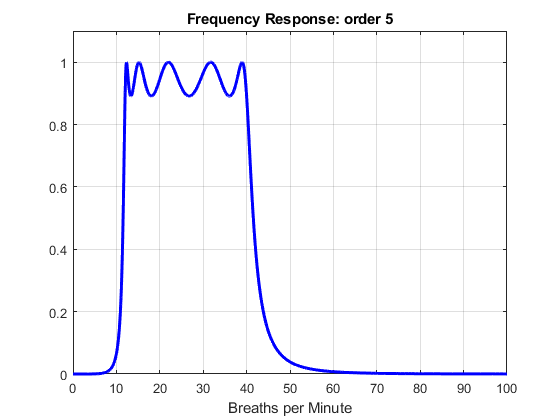


%---------------------------------------------------
% Plot cascade frequency response

fig4 = figure(4);
plot(fbpm,abs(freqz(b,a,w)),'b','linewidth',2)
grid on;
xlim(xDisplayRange); ylim([0 1.1]);
xlabel('Breaths per Minute');
title(['Frequency Response: order ',num2str(filterOrder)]);

% set(fig4,'position',figLoc);


### Print out some C-code that can be used to copy into the Arduino IDE.  To make it available for copying from the command window, execute the command 'IIR_Designer' directly in the command Window.

### First print the C-code for the Direct form of the IIR Filter

%---------------------------------------------------
% Console output transfer function coefficients in
% C declaration form

codeStr = sprintf('\n****  C Code for Direct IIR Filter -- Copy to Arduino IDE ****\n\n');


codeStr = sprintf('%s  //%s\n', codeStr, comment_txt);
codeStr = sprintf('%s  const int MFILT = %d;\n',codeStr, length(b));
bScale = max(b);
bb = b/bScale;
codeStr = sprintf('%s  static float GAIN = %0.6g;\n',codeStr, bScale);
codeStr = sprintf('%s  static float b[] = {%0.7f',codeStr,  bb(1));
% fprintf('  static float b[13] = {%0.7f',  bb(1));
for i = 2:length(bb)
    codeStr = sprintf('%s, %0.7f',codeStr, bb(i));
end
codeStr = sprintf('%s};\n', codeStr);

codeStr = sprintf('%s  static float a[] = {%0.7f', codeStr, a(1));
% fprintf('  static float a[13] = {%0.7f', a(1));
for i = 2:length(a)
    codeStr = sprintf('%s, %0.7f',codeStr, a(i));
end
codeStr = sprintf('%s};\n\n', codeStr);

fprintf('%s',codeStr)


****  C Code for Direct IIR Filter -- Copy to Arduino IDE ****

  //CHEBY bandpass, order 5, R= 1.0, [12 40] BPM

  const int MFILT = 11;
  static float GAIN = 7.3173e-05;
  static float b[] = {0.1000000, 0.0000000, -0.5000000, 0.0000000, 1.0000000, 0.0000000, -1.0000000, 0.0000000, 0.5000000, 0.0000000, -0.1000000};
  static float a[] = {1.0000000, -9.3683845, 39.8292795, -101.1903317, 170.1284222, -197.7817639, 161.0144875, -90.6420789, 33.7696618, -7.5192010, 0.7599093};



### Print the C-Code for the cascaded Second Order Sections (SOS).  This may be copied and placed into the Arduino IDE.  To make it available for copying, execute the command 'IIR_Designer' in the command window.


% %---------------------------------------------------
% % Console output sos tf coefficients in C declaration form
%
% fprintf(['  // ' comment_txt]);
% for i = 1:rsos
%     fprintf('  static float G%d = %0.7f;\n', i, Gstage(i));
%     fprintf('  static float b%d[] = {%0.7f, %0.7f, %0.7f};\n',...
%         i,sos(i,1),sos(i,2),sos(i,3));
%     fprintf('  static float a%d[] = {%0.7f, %0.7f, %0.7f};\n',...
%         i,sos(i,4),sos(i,5),sos(i,6));
% end

%---------------------------------------------------
% Console output sos tf coefficients in C declaration form

% fprintf(['// ' comment_txt]);
sSize = size(sos);
stageG = G1^(1/sSize(1));


codeStr = sprintf('\n ****  C Code for SOS Filter -- Copy to Arduino IDE ****\n');

%  Variable declarations
codeStr = sprintf('%s\n//Filter specific variable declarations\n', codeStr);
codeStr = sprintf('%sconst int numStages = %d;\n',codeStr, rsos);
codeStr = sprintf('%sstatic float G[numStages];\n', codeStr);
codeStr = sprintf('%sstatic float b[numStages][3];\n', codeStr);
codeStr = sprintf('%sstatic float a[numStages][3];\n', codeStr);

%  Variable initialization
codeStr = sprintf('%s\n\n//%s\n',codeStr, comment_txt);


for i = 1:rsos
    codeStr = sprintf('%sG[%d] = %0.7f;\n',codeStr, i-1, G1^(1/rsos));

    %     fprintf('b[%d][] = {%0.7f, %0.7f, %0.7f};\n',...
    %         i-1,sos(i,1),sos(i,2),sos(i,3));

    codeStr = sprintf('%sb[%d][0] = %0.7f; b[%d][1] = %0.7f; b[%d][2]= %0.7f;\n',...
        codeStr, i-1,sos(i,1),i-1,sos(i,2),i-1,sos(i,3));

    %     fprintf('a[%d][] = {%0.7f, %0.7f, %0.7f};\n',...
    %         i-1,sos(i,4),sos(i,5),sos(i,6));

    codeStr = sprintf('%sa[%d][0] = %0.7f; a[%d][1] =  %0.7f; a[%d][2] =  %0.7f;\n',...
        codeStr, i-1,sos(i,4),i-1, sos(i,5),i-1, sos(i,6));
end

fprintf('%s',codeStr)


 ****  C Code for SOS Filter -- Copy to Arduino IDE ****

//Filter specific variable declarations
const int numStages = 5;
static float G[numStages];
static float b[numStages][3];
static float a[numStages][3];


//CHEBY bandpass, order 5, R= 1.0, [12 40] BPM

G[0] = 0.0939443;
b[0][0] = 1.0000000; b[0][1] = -0.0000948; b[0][2]= -1.0008778;
a[0][0] = 1.0000000; a[0][1] =  -1.8024596; a[0][2] =  0.9107710;
G[1] = 0.0939443;
b[1][0] = 1.0000000; b[1][1] = 2.0002430; b[1][2]= 1.0002431;
a[1][0] = 1.0000000; a[1][1] =  -1.8673860; a[1][2] =  0.9180077;
G[2] = 0.0939443;
b[2][0] = 1.0000000; b[2][1] = 1.9993656; b[2][2]= 0.9993658;
a[2][0] = 1.0000000; a[2][1] =  -1.9332876; a[2][2] =  0.9571398;
G[3] = 0.0939443;
b[3][0] = 1.0000000; b[3][1] = -1.9992130; b[3][2]= 0.9992132;
a[3][0] = 1.0000000; a[3][1] =  -1.7932700; a[3][2] =  0.9613020;
G[4] = 0.0939443;
b[4][0] = 1.0000000; b[4][1] = -2.0003008; b[4][2]= 1.0003011;
a[4][0] = 1.0000000; a[4][1] =  -1.9719814; a[4][2] =  0.9878046;


## Print the coefficients so that they can easily be copied into MATLAB

if printMATLABFlag

    %  If the printMATLABFlag is true then output the impulse response so
    %  that it can easily be copied into MATLAB

    % fprintf('\n\nDirect IIR Filter Coefficients for easy copy to MATLAB\n\n');


    numColumns = 14;  %  Number of columns in each row


    %  Print the numerator b coefficients for easy copy to MATLAB

    bCoeffStr = '';
    for iCoeff = 1:length(b)-1


        if iCoeff == 1
            bCoeffStr = sprintf('b = [');
        end

        bCoeffStr = sprintf( '%s%3.7f',bCoeffStr, b(iCoeff) );

        if mod(iCoeff,numColumns) == 0
            bCoeffStr = sprintf( '%s,...\n', bCoeffStr);
        else
            bCoeffStr = sprintf('%s, ', bCoeffStr);
        end
    end

    % Print the last value

    bCoeffStr = sprintf( '%s%3.7f];', bCoeffStr, b(end) );

    %  Print the numerator a coefficients for easy copy to MATLAB

    aCoeffStr = '';
    for iCoeff = 1:length(a)-1


        if iCoeff == 1
            aCoeffStr = sprintf('a = [');
        end

        aCoeffStr = sprintf( '%s%3.7f', aCoeffStr, a(iCoeff) );

        if mod(iCoeff,numColumns) == 0
            aCoeffStr = sprintf( '%s,...\n', aCoeffStr);
        else
            aCoeffStr = sprintf('%s, ', aCoeffStr);
        end
    end

    % Print the last value

    aCoeffStr = sprintf( '%s%3.7f];\n', aCoeffStr, a(end) );
end

fprintf('\n\nDirect IIR Filter Coefficients for easy copy to MATLAB\n\n%s\n%s',bCoeffStr, aCoeffStr);



Direct IIR Filter Coefficients for easy copy to MATLAB

b = [0.0000073, 0.0000000, -0.0000366, 0.0000000, 0.0000732, 0.0000000, -0.0000732, 0.0000000, 0.0000366, 0.0000000, -0.0000073];
a = [1.0000000, -9.3683845, 39.8292795, -101.1903317, 170.1284222, -197.7817639, 161.0144875, -90.6420789, 33.7696618, -7.5192010, 0.7599093];




return